clear
load Data\data4.mat
n=length(data.CzasLokalnyUTC0100)

n = 3601

data.CzasLokalnyUTC0100(1:4)

ans = 4×1 datetime array
   17/06/2024 11:30:00
   17/06/2024 11:31:00
   17/06/2024 11:32:00
   17/06/2024 11:33:00


data.CzasLokalnyUTC0100(n-3:n)

ans = 4×1 datetime array
   19/06/2024 23:27:00
   19/06/2024 23:28:00
   19/06/2024 23:29:00
   19/06/2024 23:30:00


T=60; %[s]
fs=1/T; %[Hz]
t=T*(0:n-1);

Kompresor=data.StanKompresor;
StanCzujnikaZamkniecia=data.StanCzujnikZamkniciaDrzwi;

TemperaturaOtoczenia=0.1*data.TemperaturaOtoczenia;
TemperatureSterujaca=0.1*data.TemperaturaSterujca;

X=[Kompresor,StanCzujnikaZamkniecia,...
    TemperaturaOtoczenia,TemperatureSterujaca]';

[dataWithoutNans,nan_indices]  = GetRidOfNans(X);
find(nan_indices,~0)


ans =

  0×1 empty double column vector



no nans

X_toFilter=X(3:4,:);
threshold=[0,5;-5,5];
for i = 1:2
X_filtered(i,:) = InterpolateData(X_toFilter(i,:),threshold(i,:),t);
end

locs=compressorCycles(X(1,:));
x = FeatureExtract(X_filtered(2,:),locs);

f1=zeros(1,length(locs)-1);
for i=1:length(locs)-1
    f1(i)=locs(i+1)-locs(i);
end
locs=locs(2:end);

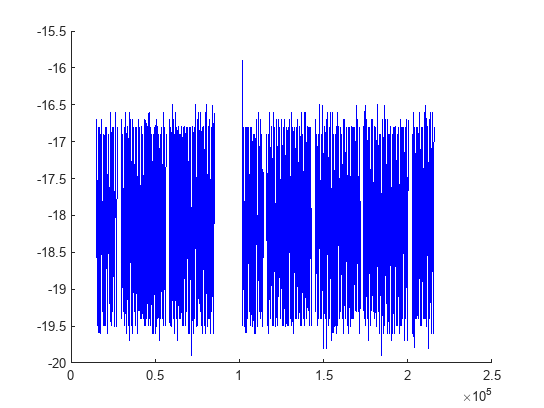

fridge_air_temp_p2p=x(1,:)-x(2,:);
indexContainer=cell(1);
indexContainer{1}=[];
set=1;
clear indexContainer
indexContainer=cell(1);
indexContainer{1}=[];
% figure
TF = isoutlier(f1);
TF2 = isoutlier(fridge_air_temp_p2p);

% plot(locs(1),(X_filtered(2,locs(1))),'Marker','o',"Color",'green');hold on
for i=2:length(x)
    
    if (TF(i)==0 && TF2(i)==0)
        % plot(locs(i-1):locs(i),(X_filtered(2,locs(i-1):locs(i))),"Color",'blue');
        % plot(locs(i),(X_filtered(2,locs(i))),'Marker','o',"Color",'green');
        indexContainer{set}=[indexContainer{set},locs(i-1):locs(i)];
    else
        if (TF(i-1)==0 || TF2(i-1)==0)
            set=set+1;
            indexContainer{set}=[];
        end
    end
end
% plot(locs,(X_filtered(4,locs)),'Marker','o',"Color",'green');
% hold off
% title('Detection of peaks on evaporator temperature')
% xlabel('Samples')
% ylabel('Temperature [C]')
set=1;
clear usableDataIndex
for i = 1:length(indexContainer)
    if length(indexContainer{i})>60
        usableDataIndex{set}=indexContainer{i};
        set=set+1;
    end
end

figure
hold on
for i = 1:length(usableDataIndex)
% for i = 1:3
    plot(t(usableDataIndex{i}),X_filtered(2,usableDataIndex{i}),'b')
end
hold off

Using both conditions, cycle lenght and p2p gave desired results.

Now using grphical analysys of the time plot and the cycle length per cyce we determine the times where the signal had different stationary parameters.

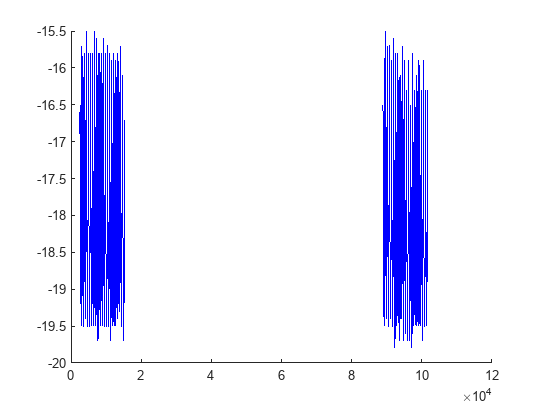

stat2ind={43:254;1483:1694}';

figure
hold on
for i = 1:length(stat2ind)
    plot(t(stat2ind{i}),X_filtered(2,stat2ind{i}),'b')
end
hold off

totalLength=0;
for i = 1:length(usableDataIndex)
totalLength=totalLength+length(usableDataIndex{i});
end
for i = 1:length(usableDataIndex)
nTrainTimes(i)=round((length(usableDataIndex{i})/totalLength)*100);
end
nTrainTimes

nTrainTimes =      7    16    16     7    16    16    15     8


other two are going to be 50 and 50

count=0;
for i = 1:length(nTrainTimes)
for j=1:nTrainTimes(i)
    count=count+1;
    rejestr1(count)=i;
    % t_sim=T*(0:length(usableDataIndex{i})-1);
    % [y{count},params{count}]=GATrain(X(1,usableDataIndex{i}), X_filtered(1,usableDataIndex{i}),...
        % t_sim, X_filtered(2,usableDataIndex{i}(1)), X_filtered(2,usableDataIndex{i}));

end
end

% save param2identification1stSet y params
load param2identification1stSet.mat
y1=y;
params1=params;

i=1;
for reps = 1:100
% for i = 1:3
    if reps>50
        i=2;
    end
    rejestr(reps)=i;
    % t_sim=T*(0:length(stat2ind{i})-1);
    % [y{reps},params{reps}]=GATrain(X(1,stat2ind{i}), X_filtered(1,stat2ind{i}),...
        % t_sim, X_filtered(2,stat2ind{i}(1)), X_filtered(2,stat2ind{i}));
end

% save param2identification2ndSet y params
load param2identification2ndSet.mat

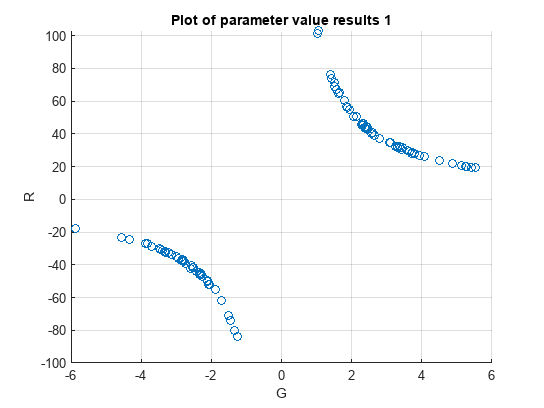

for i = 1:length(params1)
resu1(i,:)=params1{i};
end


figure
plot3(resu1(:,1),resu1(:,2),resu1(:,3),'o');
grid on
xlabel('G')
ylabel('R')
zlabel('C')
title('Plot of parameter value results 1')
% view(0,0)
view(0,90)

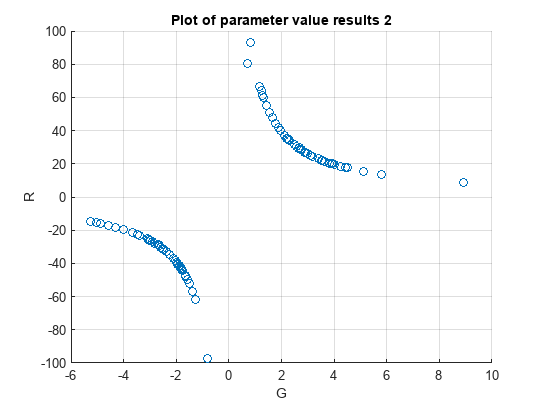

for i = 1:length(params)
resu(i,:)=params{i};
end


figure
plot3(resu(:,1),resu(:,2),resu(:,3),'o');
grid on
xlabel('G')
ylabel('R')
zlabel('C')
title('Plot of parameter value results 2')
% view(0,0)
view(0,90)

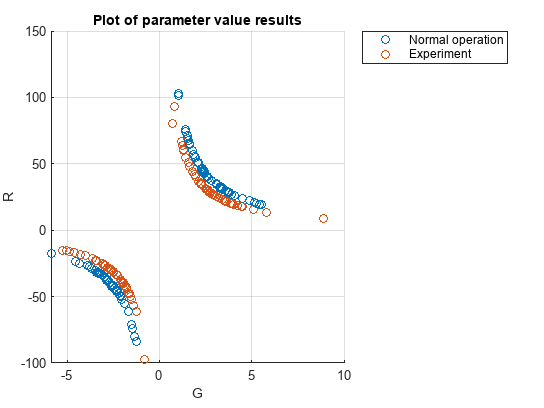




figure
plot3(resu1(:,1),resu1(:,2),resu1(:,3),'o');hold on
plot3(resu(:,1),resu(:,2),resu(:,3),'o');hold off
legend('Normal operation','Experiment')
grid on
xlabel('G')
ylabel('R')
zlabel('C')
title('Plot of parameter value results')
% view(0,0)
view(0,90)

% view(90,0)

for i = 1:length(params1)
rmse_mat1(i)=rmse(X_filtered(2,usableDataIndex{rejestr1(i)}),y1{i}');
end

[rmse_mat_sorted1, sort_indeces1] = sort(rmse_mat1);

for i = 1:length(params)
rmse_mat(i)=rmse(X_filtered(2,stat2ind{rejestr(i)}),y{i}');
end

[rmse_mat_sorted, sort_indeces] = sort(rmse_mat);

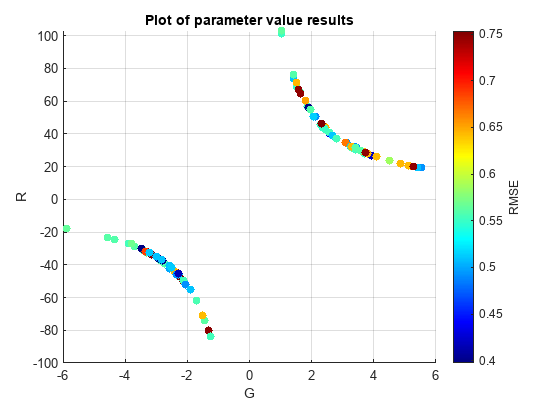

figure;
scatter3(resu1(:,1),resu1(:,2),resu1(:,3), [], rmse_mat1, 'filled');
% Set the colormap
colormap(jet); % You can use other colormaps like 'hot', 'parula', etc.

% Add colorbar

c=colorbar;
c.Label.String = 'RMSE';
grid on
xlabel('G')
ylabel('R')
zlabel('C')
title('Plot of parameter value results')
% view(0,0)
view(0,90)

% view(90,0)

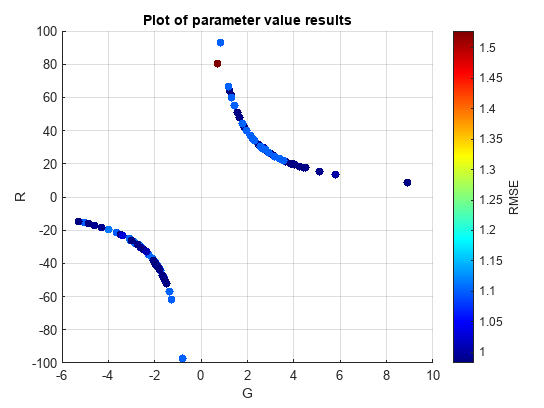

figure;
scatter3(resu(:,1),resu(:,2),resu(:,3), [], rmse_mat, 'filled');
% Set the colormap
colormap(jet); % You can use other colormaps like 'hot', 'parula', etc.

% Add colorbar

c=colorbar;
c.Label.String = 'RMSE';
grid on
xlabel('G')
ylabel('R')
zlabel('C')
title('Plot of parameter value results')
% view(0,0)
view(0,90)

% view(90,0)

Time response analysis

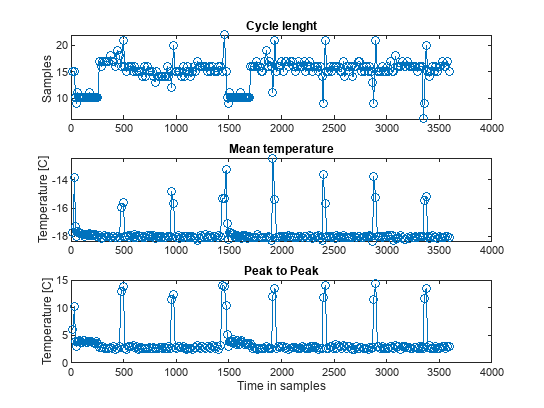

figure 
subplot(311)
plot(locs,f1,'o-')
title('Cycle lenght')
ylabel('Samples ')
subplot(312)
plot(locs,x(3,:),'o-')
title('Mean temperature')
ylabel('Temperature [C]')
subplot(313)
plot(locs,x(1,:)-x(2,:),'o-')
title('Peak to Peak')
xlabel('Time in samples')
ylabel('Temperature [C]')

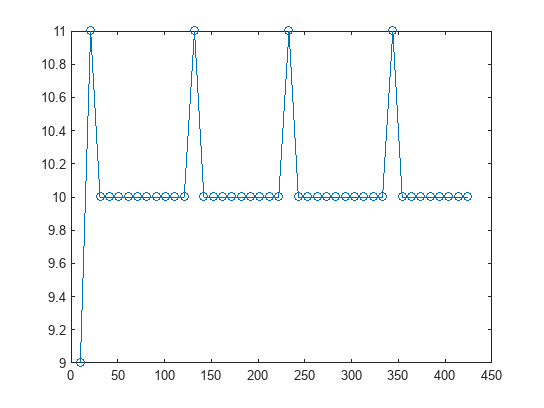

c1 = FeatureExtract(X_filtered(2,[stat2ind{1},stat2ind{2}]),compressorCycles(X(1,[stat2ind{1},stat2ind{2}])));
locs2=compressorCycles(X(1,[stat2ind{1},stat2ind{2}]));
for i=1:length(locs2)-1
    f12(i)=locs2(i+1)-locs2(i);
end
locs2=locs2(2:end);
figure
plot(locs2,f12,'o-')

length is 10 samples

c1=10

c1 = 10

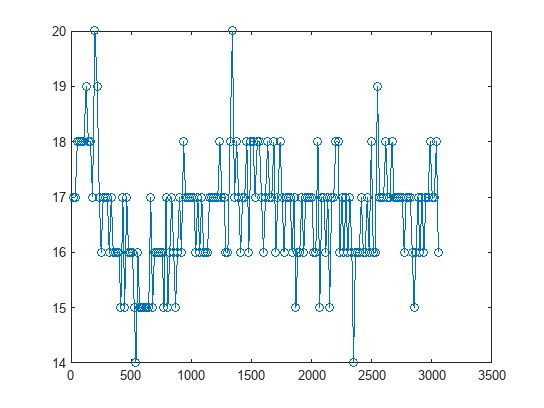

unfold_usableDataIndex=usableDataIndex{1};
for i=2:length(usableDataIndex)
    unfold_usableDataIndex=[unfold_usableDataIndex,usableDataIndex{i}];
end

locs3=compressorCycles(X(1,unfold_usableDataIndex));
for i=1:length(locs3)-1
    f13(i)=locs3(i+1)-locs3(i);
end
locs3=locs3(2:end);
figure
plot(locs3,f13,'o-')

c2=mean(f13)

c2 = 16.6831

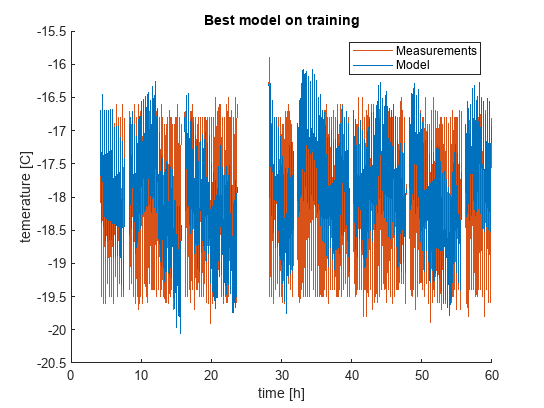

TrainingFraction=0.8;  % percent of dataset used for training
TrainingNumber=floor(TrainingFraction*length(usableDataIndex));
TrainingData=usableDataIndex(1:TrainingNumber);
TrainingSet=TrainingData;
[bestParameter2,ind2]=bestOfDataSet(usableDataIndex,params1,T,X(2,:),...
    X_filtered(2,:),X_filtered(1,:),1);
figure
hold on
for i = 1:length(usableDataIndex)
% for i = 1:3
    t_sim=T*(0:length(usableDataIndex{i})-1);
    y_tmp=ModelFunction(-X(1,usableDataIndex{i})', X_filtered(1,usableDataIndex{i})',...
            bestParameter2{1}(1), bestParameter2{1}(2), bestParameter2{1}(3),...
            t_sim, X_filtered(2,usableDataIndex{i}(1)))';

    plot(t(usableDataIndex{i})/(60*60),X_filtered(2,usableDataIndex{i}),'Color','#D95319')
    plot(t(usableDataIndex{i})/(60*60),y_tmp,'Color','#0072BD')
end
hold off
title('Best model on training')
xlabel('time [h]')
ylabel('temerature [C]')
legend('Measurements','Model')

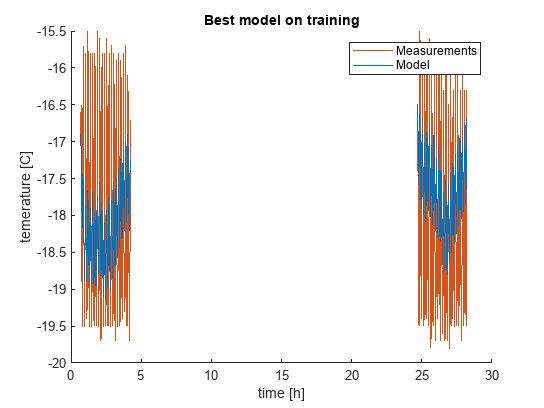

[bestParameter,ind]=bestOfDataSet(stat2ind,params,T,X(2,:),...
    X_filtered(2,:),X_filtered(1,:),1);

figure
hold on
for i = 1:length(stat2ind)
% for i = 1:3
    t_sim=T*(0:length(stat2ind{i})-1);
    y_tmp=ModelFunction(-X(1,stat2ind{i})', X_filtered(1,stat2ind{i})',...
            bestParameter{1}(1), bestParameter{1}(2), bestParameter{1}(3),...
            t_sim, X_filtered(2,stat2ind{i}(1)))';

    plot(t(stat2ind{i})/(60*60),X_filtered(2,stat2ind{i}),'Color','#D95319')
    plot(t(stat2ind{i})/(60*60),y_tmp,'Color','#0072BD')
end
hold off
title('Best model on training')
xlabel('time [h]')
ylabel('temerature [C]')
legend('Measurements','Model')

t1=T*(0:c1-1);
t2=T*(0:c2-1);

from 83  103

from 1005 to 1035

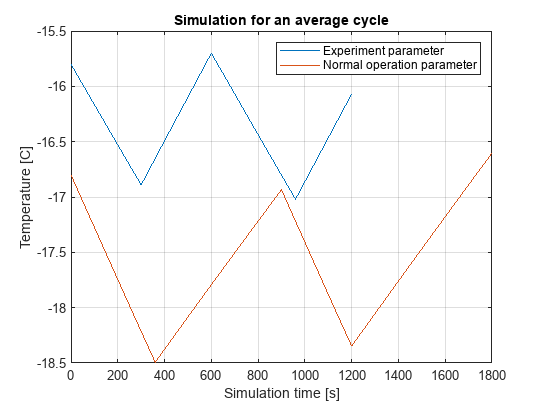


% x1=X(1,83:103)
% Ta1=X_filtered(1,83:103)
% response1=[zeros(1,c1/2),ones(1,c1/2)];
% response1 = ModelFunction(x1,Ta1,G,R,C,t,x0)

t_sim1=T*(0:length(83:103)-1);
    response1=ModelFunction(-X(1,83:103)', X_filtered(1,83:103)',...
            bestParameter{1}(1), bestParameter{1}(2), bestParameter{1}(3),...
            t_sim1, X_filtered(2,83))';

t_sim2=T*(0:length(1005:1035)-1);
response2=ModelFunction(-X(1,1005:1035)', X_filtered(1,1005:1035)',...
            bestParameter2{1}(1), bestParameter2{1}(2), bestParameter2{1}(3),...
            t_sim2, X_filtered(2,1005))';
figure

plot(t_sim1,response1);hold on
plot(t_sim2,response2)
title('Simulation for an average cycle')
xlabel('Simulation time [s]')
ylabel('Temperature [C]')
legend('Experiment parameter','Normal operation parameter')
grid on

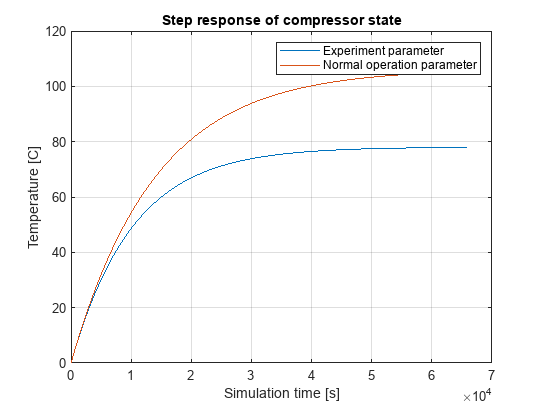

window_len=1100;
t_sim1=T*(0:window_len-1);
step_response1=ModelFunction(ones(1,window_len)', zeros(1,window_len)',...
            bestParameter{1}(1), bestParameter{1}(2), bestParameter{1}(3),...
            t_sim1, 0);

t_sim2=T*(0:window_len-1);
step_response2=ModelFunction(ones(1,window_len)', zeros(1,window_len)',...
            bestParameter2{1}(1), bestParameter2{1}(2), bestParameter2{1}(3),...
            t_sim2, 0);
figure

plot(t_sim1,step_response1);hold on
plot(t_sim2,step_response2)
title('Step response of compressor state')
xlabel('Simulation time [s]')
ylabel('Temperature [C]')
legend('Experiment parameter','Normal operation parameter')
grid on

function [bestParameter,ind]=bestOfDataSet(TrainingSet,params,T,x,y,Ta,hasToBePositive)

if hasToBePositive == []
    hasToBePositive=0;
end


averageRMSE=NaN(1,length(TrainingSet));
parfor j=1:length(TrainingSet) %for parameter set j
    RMSE_on_all=NaN(1,length(TrainingSet));
    for i=1:length(TrainingSet) %check rmse of j parameter set on all data chinks
        t_sim=T*(0:length(TrainingSet{i})-1);
        RMSE_on_all(i) = costFunction(-x(TrainingSet{i})', Ta(TrainingSet{i})',...
            params{j}(1), params{j}(2), params{j}(3),...
            t_sim, y(TrainingSet{i}(1)), y(TrainingSet{i}));
    end

    if any(isnan(RMSE_on_all), 'all')
        error('Array RMSE_on_all contains NaN values.');
    end

    averageRMSE(j)=mean(RMSE_on_all); %average rmse for j parameter set on all data chunks

end

if any(isnan(averageRMSE), 'all')
    error('Array averageRMSE contains NaN values.');
end

[~,ind] = min(averageRMSE);
bestParameter=params(ind);

if hasToBePositive == 1
    count=0;
    while all(bestParameter{1}<[0,0,0])
        bestParameter=params(ind+count);
        count=count+1;
    end
end
end
